clear
clc
syms K_B1 K_B2 theta_1 A theta_2 beta phi_2 phi_1 
syms Phi_1 Phi_2 Theta_1 Theta_2
zeta = deg2rad(180);

eq = ( A*cos(phi_1)+K_B2*theta_2*cos(phi_2-zeta) )^2 + ( A*sin(phi_1)+K_B2*theta_2*sin(phi_2-zeta) )^2 - ((K_B1^2) * (Theta_1^2)) == 0;
solve_1 = (solve(eq,Theta_1));
sol_1 = simplify(solve_1)

$$sol\_1 = \left(\begin{array}{c} \frac{\sqrt{A^{2}-2\,\cos\left(\varphi_{1}-\varphi_{2}\right)\,A\,K_{\mathrm{B2}}\,\theta_{2}+{K_{\mathrm{B2}}}^{2}\,{\theta_{2}}^{2}}}{K_{\mathrm{B1}}}\\ -\frac{\sqrt{A^{2}-2\,\cos\left(\varphi_{1}-\varphi_{2}\right)\,A\,K_{\mathrm{B2}}\,\theta_{2}+{K_{\mathrm{B2}}}^{2}\,{\theta_{2}}^{2}}}{K_{\mathrm{B1}}} \end{array}\right)$$

Theta_1 = sol_1(1,1)

$$Theta\_1 = \frac{\sqrt{A^{2}-2\,\cos\left(\varphi_{1}-\varphi_{2}\right)\,A\,K_{\mathrm{B2}}\,\theta_{2}+{K_{\mathrm{B2}}}^{2}\,{\theta_{2}}^{2}}}{K_{\mathrm{B1}}}$$


eq_2 = K_B1*sol_1(1,1)*cos(Phi_1) - A*cos(phi_1) - K_B2*theta_2*cos(phi_2-zeta) == 0;
solve_2 = solve(eq_2,Phi_1)

$$solve\_2 = \begin{array}{l} \left(\begin{array}{c} -\sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{acos}\left(\frac{A\,\cos\left(\varphi_{1}\right)-K_{\mathrm{B2}}\,\theta_{2}\,\cos\left(\varphi_{2}\right)}{\sqrt{A^{2}-2\,\cos\left(\varphi_{1}-\varphi_{2}\right)\,A\,K_{\mathrm{B2}}\,\theta_{2}+{K_{\mathrm{B2}}}^{2}\,{\theta_{2}}^{2}}}\right) \end{array}$$

sol_2 = simplify(solve_2)

$$sol\_2 = \begin{array}{l} \left(\begin{array}{c} -\sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{acos}\left(\frac{A\,\cos\left(\varphi_{1}\right)-K_{\mathrm{B2}}\,\theta_{2}\,\cos\left(\varphi_{2}\right)}{\sqrt{A^{2}-2\,\cos\left(\varphi_{1}-\varphi_{2}\right)\,A\,K_{\mathrm{B2}}\,\theta_{2}+{K_{\mathrm{B2}}}^{2}\,{\theta_{2}}^{2}}}\right) \end{array}$$

%Phi_1 = sol_2(2,1)

eq_3 = K_B1*sol_1(1,1)*sin(Phi_1) - A*sin(phi_1) - K_B2*theta_2*sin(phi_2-zeta) == 0;
solve_3 = solve(eq_3,Phi_1);
sol_3 = simplify(solve_3)

$$sol\_3 = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}\\ \pi -\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{asin}\left(\frac{A\,\sin\left(\varphi_{1}\right)-K_{\mathrm{B2}}\,\theta_{2}\,\sin\left(\varphi_{2}\right)}{\sqrt{A^{2}-2\,\cos\left(\varphi_{1}-\varphi_{2}\right)\,A\,K_{\mathrm{B2}}\,\theta_{2}+{K_{\mathrm{B2}}}^{2}\,{\theta_{2}}^{2}}}\right) \end{array}$$


Phi_1_tan = atan2(cos(sol_2(2,1)),sin(sol_3(1,1)))

$$Phi\_1\_tan = \text{atan2}\left(\frac{A\,\cos\left(\varphi_{1}\right)-K_{\mathrm{B2}}\,\theta_{2}\,\cos\left(\varphi_{2}\right)}{\sqrt{A^{2}-2\,\cos\left(\varphi_{1}-\varphi_{2}\right)\,A\,K_{\mathrm{B2}}\,\theta_{2}+{K_{\mathrm{B2}}}^{2}\,{\theta_{2}}^{2}}},\frac{A\,\sin\left(\varphi_{1}\right)-K_{\mathrm{B2}}\,\theta_{2}\,\sin\left(\varphi_{2}\right)}{\sqrt{A^{2}-2\,\cos\left(\varphi_{1}-\varphi_{2}\right)\,A\,K_{\mathrm{B2}}\,\theta_{2}+{K_{\mathrm{B2}}}^{2}\,{\theta_{2}}^{2}}}\right)$$


Phi_1_tan = -real(Phi_1_tan) + pi;

for i = 1:length(Phi_1_tan)
    if Phi_1_tan(i) > pi
        Phi_1_tan(i) = Phi_1_tan(i) - pi;  
    end
end

Conversion to logical from sym is not possible.


eq = (K_B1*Theta_1*cos(Phi_1))^2 + (K_B1*Theta_1*sin(Phi_1))^2 ==...
    ((A*cos(phi_1) + K_B2*theta_2*cos(phi_2-zeta)))^2 *...
    ((A*sin(phi_1) + K_B2*theta_2*sin(phi_2-zeta)))^2 ;
solve = solve(eq,Phi_1);
sol = simplify(solve)

 
sol =
 
Empty sym: 0-by-1
 


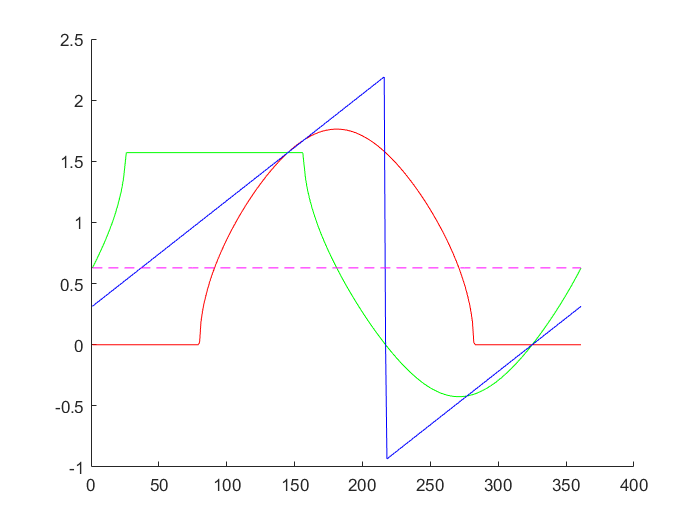

clear
clc
clf

i = 1;
phi_1 = pi/5;
for phi_2 = -pi:deg2rad(1):pi
    Phi_1_cos(i) = acos((cos(phi_1)-cos(phi_2)));
    Phi_1_sin(i) = asin((sin(phi_1)-sin(phi_2)));
    Phi_1_tan(i) = atan2(real(cos(Phi_1_cos(i))),real(sin(Phi_1_sin(i))));
    i = i + 1;
end

Phi_1_tan = -real(Phi_1_tan) + pi/2;

%%
figure(1)
hold on
plot(real(Phi_1_cos),'r-');
plot(real(Phi_1_sin),'g-');
plot(real(Phi_1_tan),'b-');
plot(phi_1*ones(1,length(Phi_1_sin)),'m--')